**Công thức tính hàm gamma : **

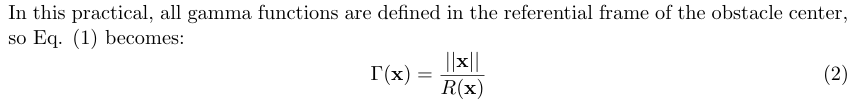

**Công thức tính gamma gradient : Đạo hàm của hàm gama.**

**TASK1: ** **Program the gamma function and its gradient for a vertical, infinite length cylinder.**

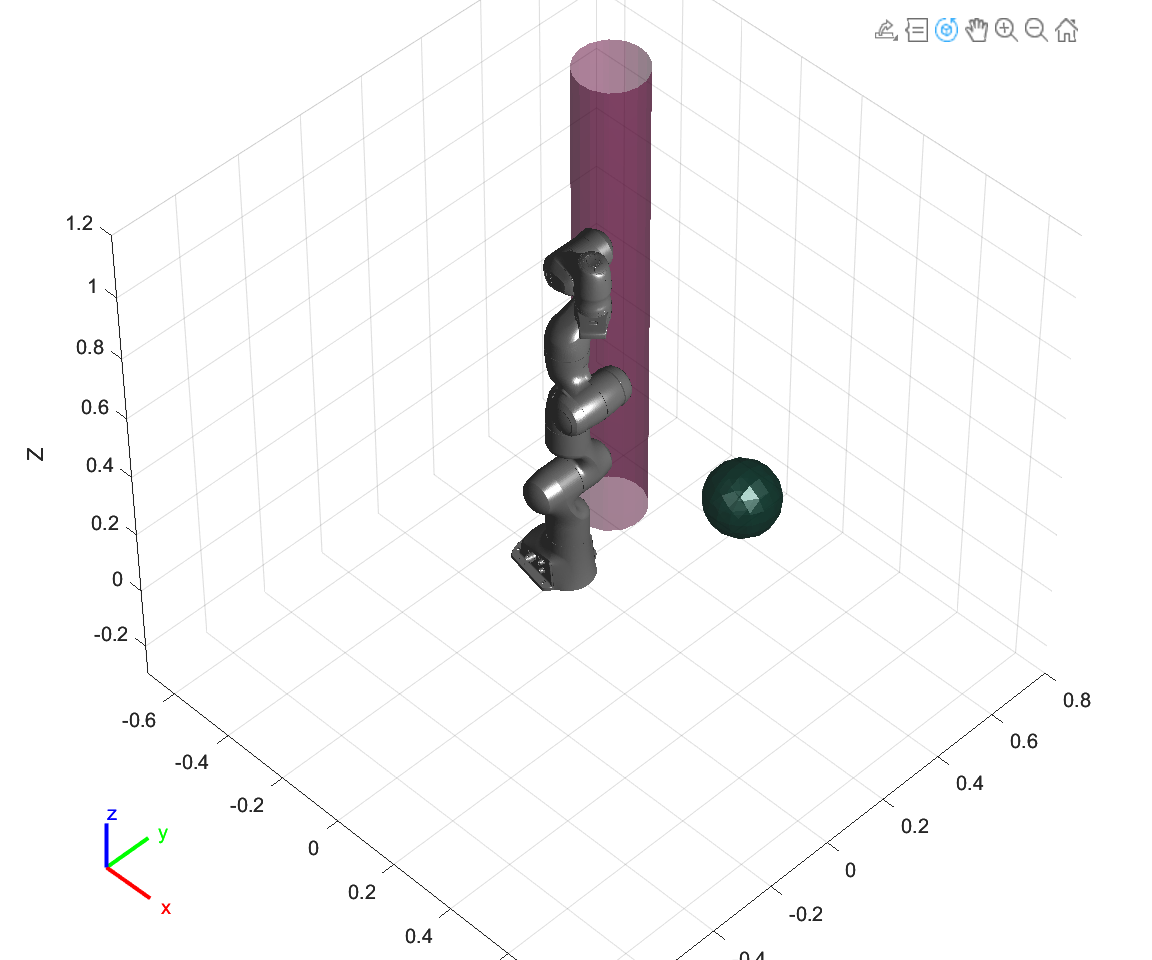

% function val = gamma(x,y,param) %do trục z vô hạn nên có thẻ bỏ z k dùng
% val=sqrt(x.^2+y.^2)/param.radius;
% end 
%cách viết khác
%gamma = @(x, y, z, param) sqrt(x.^2 + y.^2) / param.radius;
%gradientGamma = @(x, y, z, param) [x ./ (param.radius .* sqrt(x.^2 + y.^2)); y ./ (param.radius .* sqrt(x.^2 + y.^2));0.*z];
folder = fileparts(which('practical2_main.m'));
addpath(genpath(fullfile(folder, 'library')));

myworld=Environment([0; 0; 0]);

myworld.addCylinder(0.1, [-0.3, 0.45, 1]);
myworld.addEllipsoid([0.1,0.1, 0.1], [0.4, 0.2, 0.4]);

** TASK 2 Program the gamma function and its gradient for a 3D ellipsoid.**

% param = struct();
% param.ellipseAxes = axes; % [a; b; c]
% mu=@(x,y,z,param) 1 ./ sqrt((x ./ param.ellipseAxes(1)).^2 + (y ./ param.ellipseAxes(2)).^2 + (z ./ param.ellipseAxes(3)).^2 );
% gamma=@(x,y,z,param) 1./mu(x,y,z,param);
% gradientGamma = @(x, y, z, param) [x ./ (param.ellipseAxes(1).^2).* gamma(x, y, z, param);... 
% y ./ (param.ellipseAxes(2).^2) .* gamma(x, y, z, param);...
% z ./ (param.ellipseAxes(3).^2) .* gamma(x, y, z, param)];
